
weed_filename = "C:\Users\emper\Desktop\Line and Row Detect\Corn_Soybean_cotton_weed\Cotton\Cotton Continuous 1.jpg"

weed_filename = "C:\Users\emper\Desktop\Line and Row Detect\Corn_Soybean_cotton_weed\Cotton\Cotton Continuous 1.jpg"

raw_img = imread(weed_filename);
ExG_img = 2*raw_img(:,:,2)-raw_img(:,:,1)-raw_img(:,:,3)

ExG_img = 726×1020 uint8 矩阵
    3    7   12   25   33   43   47   53   53   51   46   38   29   21   14   11    7    6    0    0    0    0    0    0    0    0    0   12   20   32   33   42   54   55   48   48   43   41   39   35   27   26   14    5    0    0    0    0    0    0
    6   10   19   26   35   43   51   53   53   53   46   38   29   24   14   11    7    3    0    0    0    0    0    0    0    0    5   15   23   32   38   45   54   53   48   46   43   41   39   32   27   22   14    5    0    0    0    0    0    0
   10   12   21   29   38   46   53   56   56   53   46   40   33   24   14   11    2    0    0    0    0    0    0    0    0    0    6   18   26   33   42   45   50   53   48   46   40   38   36   30   26   17   10    2    0    0    0    0    0    0
   19   21   26   35   43   47   53   56   56   53   46   38   29   22   18   11    1    0    0    0    0    0    0    0    0    5   12   23   31   36   45   49   50   51   46   40   38   32   30   26   17   14    5    

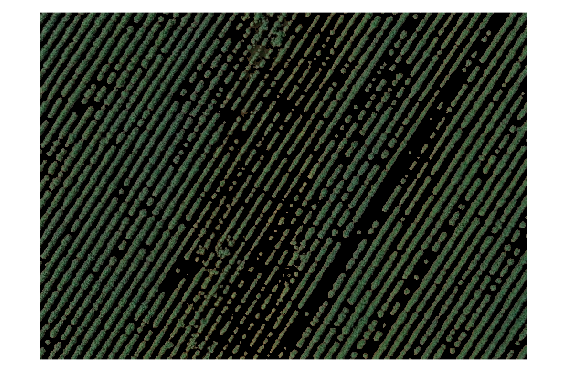

ExG_mask = uint8(ExG_img>0);
ExG_masked_img = ExG_mask.*raw_img;
imshow(ExG_masked_img);

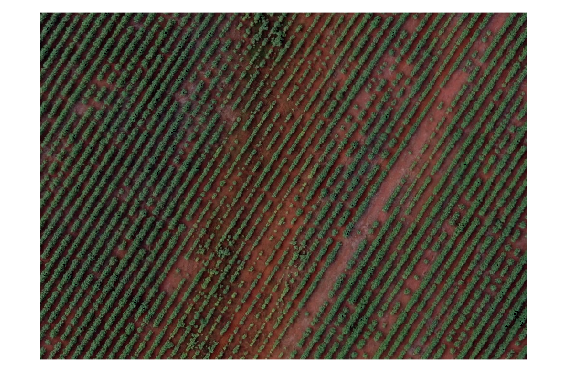

ExR_img = 1.4*raw_img(:,:,1)-raw_img(:,:,3);
ExR_mask = uint8(ExR_img>0);
imshow(ExR_mask.*raw_img);

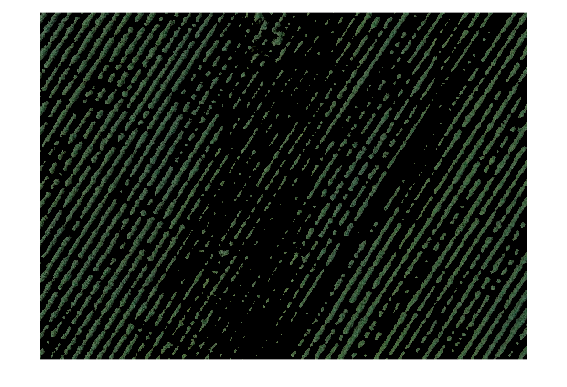

ExGR_trsh = graythresh(ExG_img-ExR_img);
ExGR_mask = uint8(ExG_img-ExR_img>ExGR_trsh-0.06);
ExGR_masked_img = ExGR_mask.*raw_img;
imshow(ExGR_masked_img);

%rotation
degs = zeros(180, 1)

degs =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


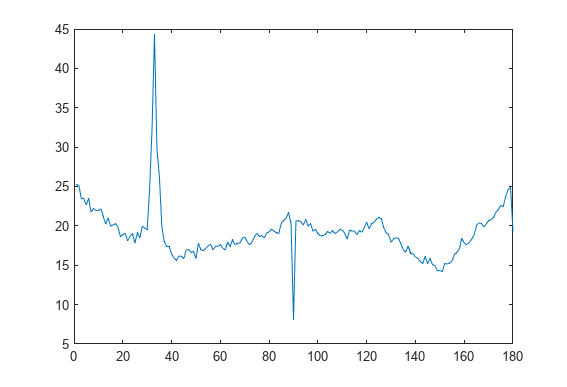

for deg = 1:180
    rotated_img = imrotate(ExG_masked_img, deg);
    col_means = max(mean(2*rotated_img(:,:,2)-rotated_img(:,:,1)-rotated_img(:,:,3)))-min(mean(2*rotated_img(:,:,2)-rotated_img(:,:,1)-rotated_img(:,:,3)));
    degs(deg) = col_means;
end
plot(degs)

[~, idx] = max(degs);
raw_img_r = imrotate(raw_img, idx);
ExG_mask_r = imrotate(ExG_mask, idx);
ExGR_mask_r = imrotate(ExGR_mask, idx);

ExG_mask_filled = imfill(ExG_mask_r, 26, "holes");
ExGR_mask_filled = imfill(ExGR_mask_r, 26, "holes");
img_r_filled = ExG_mask_filled.*raw_img_r;
%img_r_filled = ExGR_mask_filled.*raw_img_r;


[N, M, ~] = size(img_r_filled);
ROI = 2*img_r_filled(:,:,2)-img_r_filled(:,:,1)-img_r_filled(:,:,3);

ROI = im2bw(ROI, graythresh(ROI));

top = zeros(1, M);
bot = zeros(1, M);

top_full = zeros(1, M);
bot_full = zeros(1, M);
%for each row
for j = 1:M
    cur = find(ROI(:, j)>0);
    cur_full = find(raw_img_r(:, j, 1)>0& raw_img_r(:, j, 2)>0 &raw_img_r(:, j, 3)>0);
    if ~isempty(cur) && cur(1)~=cur(end)
        top(j) = cur(1);
        bot(j) = cur(end);
    else
        top(j) = 1;
        bot(j) = N;
    end
    if ~isempty(cur_full)
        top_full(j) = cur_full(1);
        bot_full(j) = cur_full(end);
    else
        top_full(j) = 1;
        bot_full(j) = N;
    end
end

valid_length = bot-top+1;
full_length = bot_full-top_full+1;
non_zeros = find(sum(ROI)./full_length>0.4)

non_zeros =      4     5     6     7     8     9    10    11    12    13    14    26    27    28    29    30    31    32    33    34    35    48    49    50    51    52    53    54    55    56    57    68    69    70    71    72    73    74    75    76    89    90    91    92    93    94    95    96    97    98


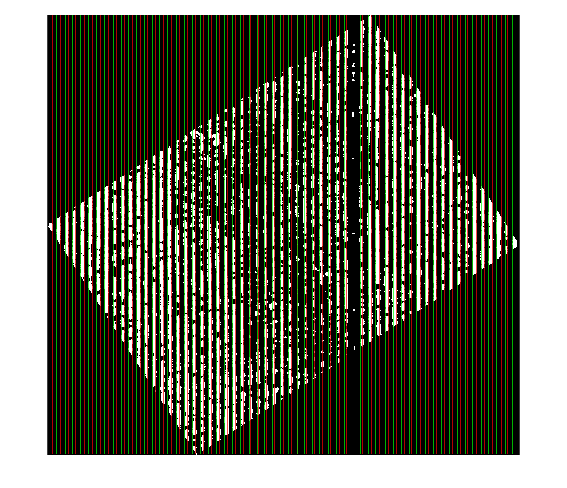

%non_zeros = find(sum(ROI)./valid_length>0.6)

l_end = zeros(1, 1);
r_end = zeros(1, 1);
for i = 1:length(non_zeros)-1
        if (non_zeros(i+1)-non_zeros(i)>=4)
            r_end = [r_end; non_zeros(i)];
            l_end = [l_end; non_zeros(i+1)];
        end
end

% uicontrol("HandleVisibility","off");

% cols = sum(ROI)
% m = median(sum(ROI))
% max_l_end = zeros(1,1)
% min_r_end = zeros(1,1)
% N_bed = -inf;
% 
% find(cols>=m)&&find(cols<m)
% 
% 
% % for c = 2:N
% %     for r = 2:M
% %         l_end = find(sum(ROI(:, c))>median(sum(ROI)) & sum(ROI(:, c-1))<=median(sum(ROI)));
% %         r_end = find(sum(ROI(:, c))>median(sum(ROI)) & sum(ROI(:, c+1))<=median(sum(ROI)));
% %         if length(l_end) > N_bed
% %             max_l_end = l_end;
% %             min_r_end = r_end;
% %             N_bed = length(l_end);
% %         elseif length(l_end) == N_bed
% %             max_l_end = max(max_l_end, l_end);
% %             min_r_end = min(min_r_end, r_end);
% %         end
% %     end
% % end
figure;
imshow(ROI);
hold on;
xline(r_end,'r');
xline(l_end,'g');
hold off;

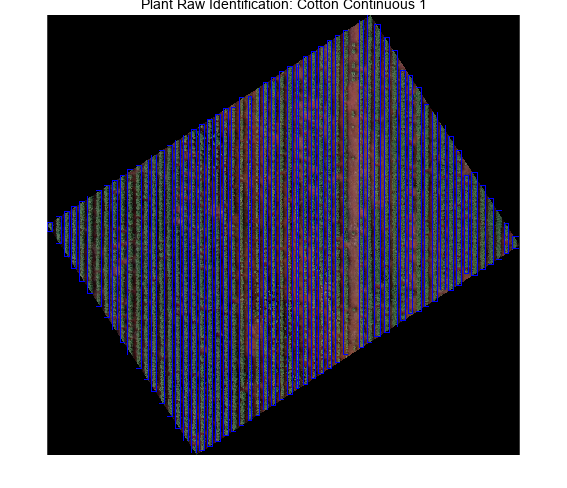


rm = find(top==1&bot==N);
top(rm) = inf;
bot(rm) = -inf;
width_adjust = 2;
annotatedImage = raw_img_r;
first_bbox = [1, min(top(1:r_end(2))) r_end(2)-1 max(bot(1:r_end(2)))-min(top(1:r_end(2)))+1];
annotatedImage = insertShape(annotatedImage,"rectangle",first_bbox,"LineWidth",2,'Color','blue');
last_bbox = [l_end(end), min(top(l_end(end):M)) M-l_end(end)-1 max(bot(l_end(end):M))-min(top(l_end(end):M))];
annotatedImage = insertShape(annotatedImage,"rectangle",last_bbox,"LineWidth",2,'Color','blue');
for l = 1:length(r_end)-2
    ll = l_end(l+1);
    rr = r_end(l+2);
    tt = min(top(ll:rr));
    bb = max(bot(ll:rr));
    bbox = [ll-width_adjust tt rr-ll+1+width_adjust*2 bb-tt+1];
    label = "plant row";
    annotatedImage = insertShape(annotatedImage,"rectangle",bbox,"LineWidth",2,'Color','blue');
end
imshow(annotatedImage)
title('Plant Raw Identification: Cotton Continuous 1')